# GWSC-Lab1

## Signal generation - 2021-02-21

### Sinusoidal signal

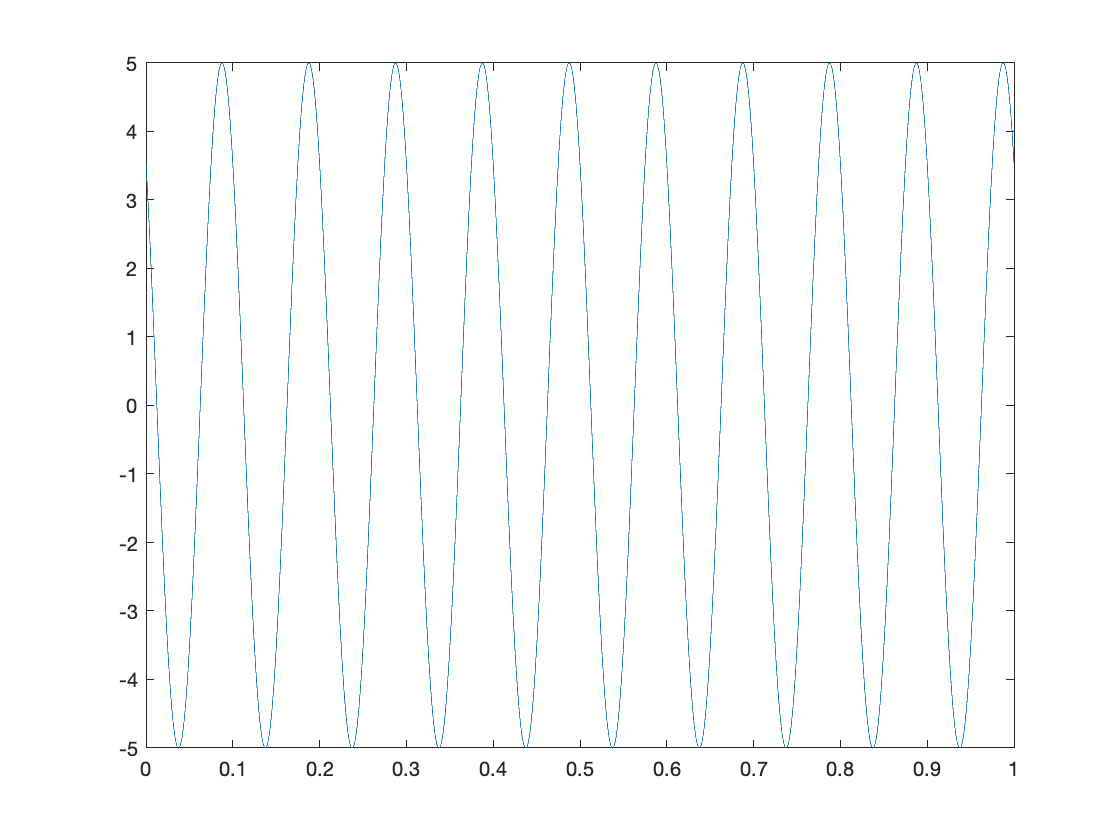

T = 1; % total secs
N = 10^4; % number of points
dt = 1/N;
t = 0:dt:1;
snr = 5;
freq = 10;
phi0 = 3/4*pi;
sigVec = genSinSig(t,snr,freq,phi0);
plot(t,sigVec)

### Linear chirp signal

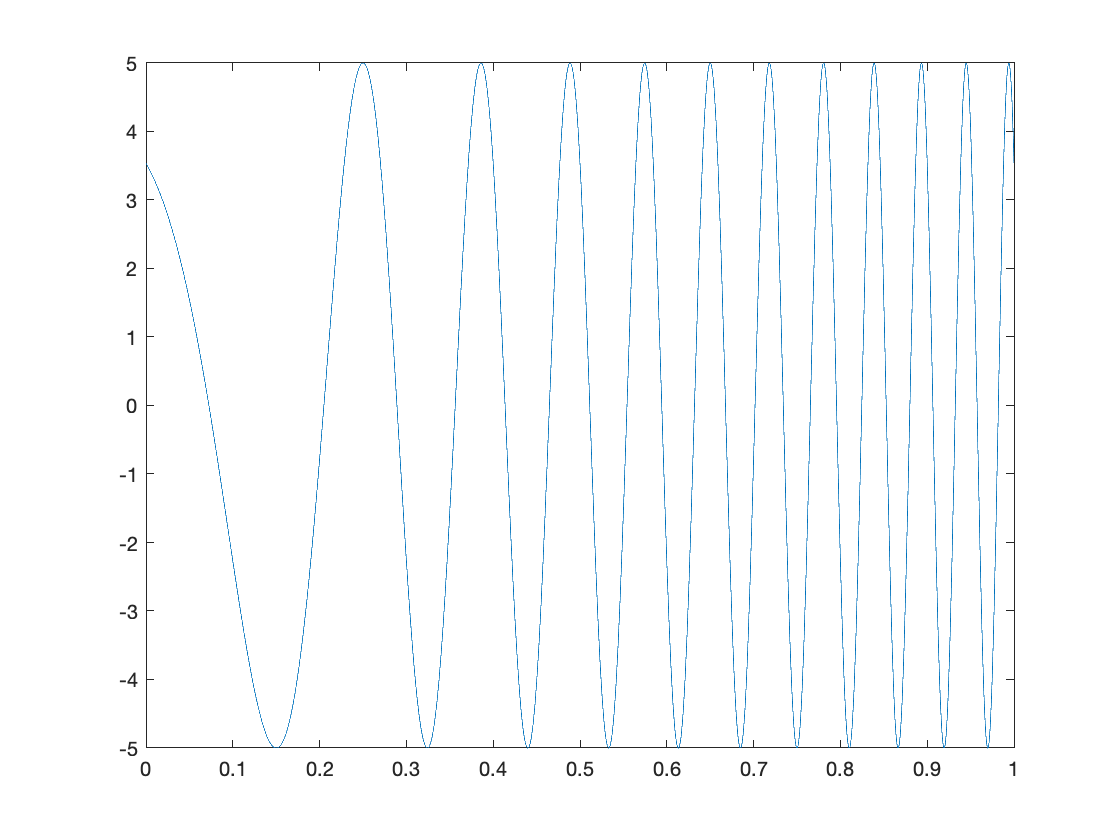

f0 = 1;
f1 = 10;
sigVec = LinearChirp(t,snr,f0,f1,phi0);
plot(t,sigVec)

### Sine-Gaussian signal

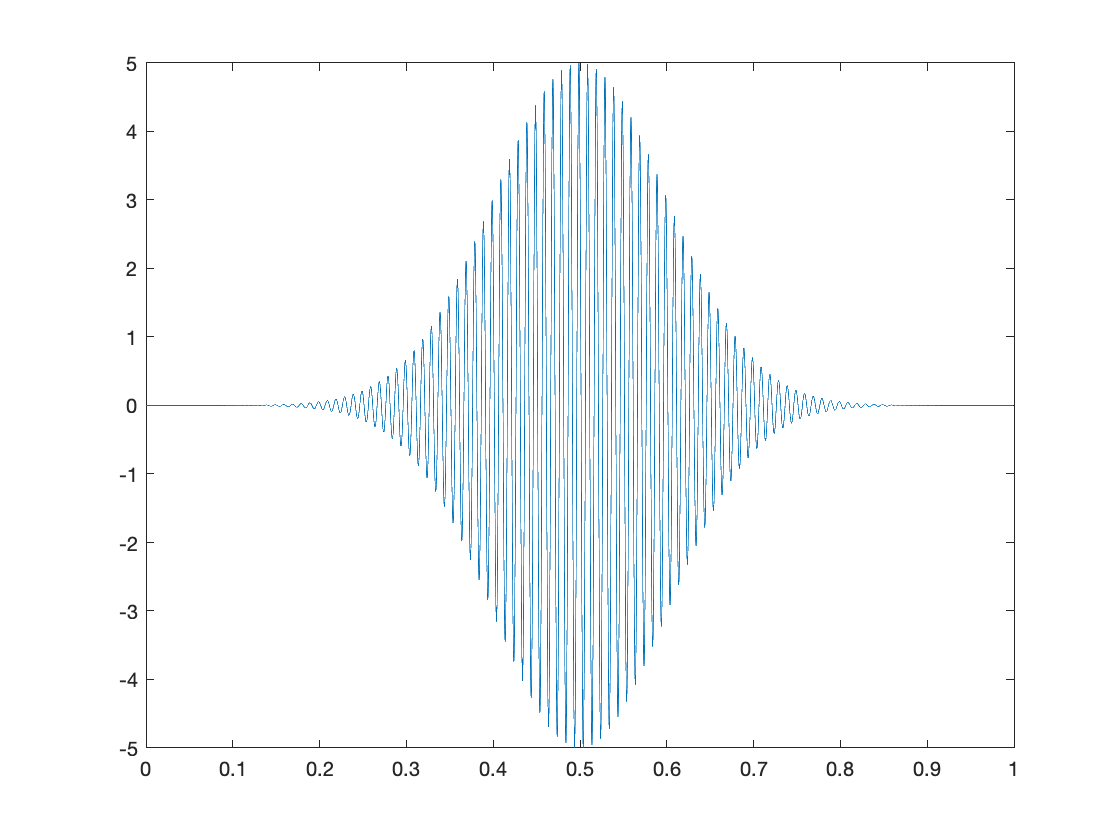

t0 = 0.5;
f0 = 100;
s = 0.1;
sigVec = SinGausian(t,snr,t0,s,f0,phi0);
plot(t,sigVec)

### Frequency Modulated Sinusoidal signal

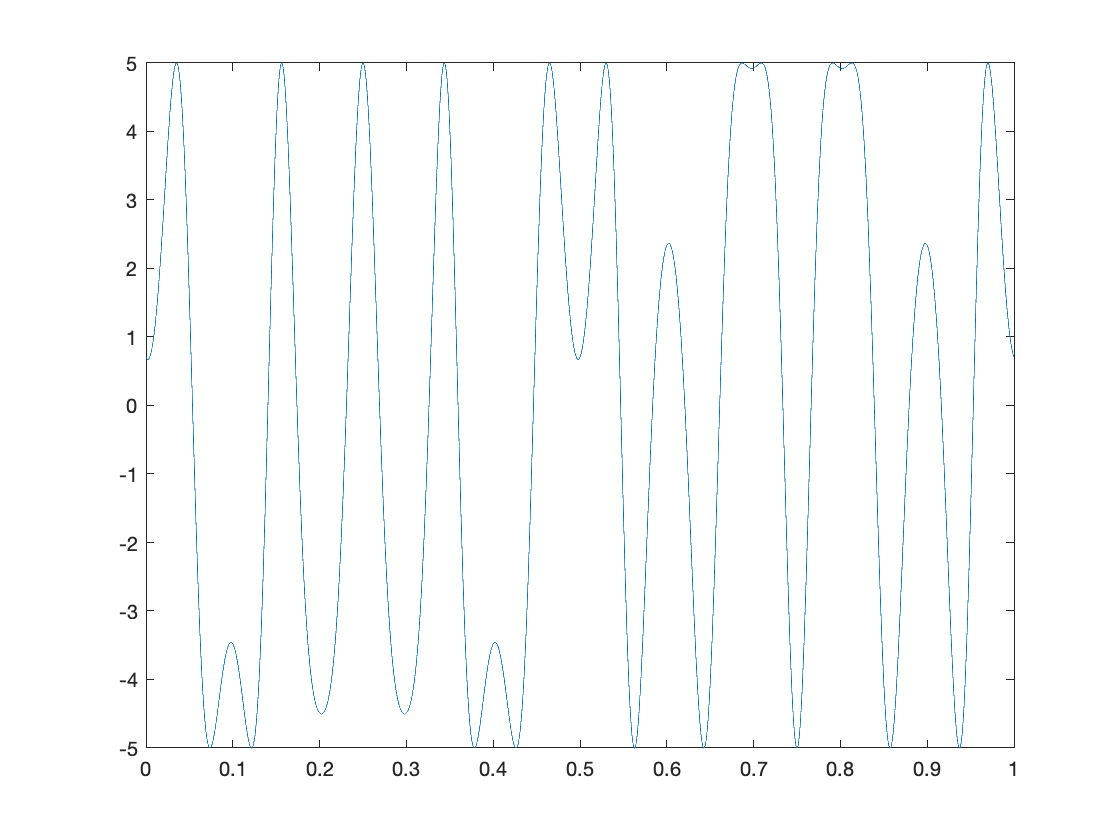

b = 3;
f0 = 1;
f1 = 5;
sigVec = FMSin(t,snr,b,f0,f1);
plot(t,sigVec)

### Amplitude modulated sinusoidal signal

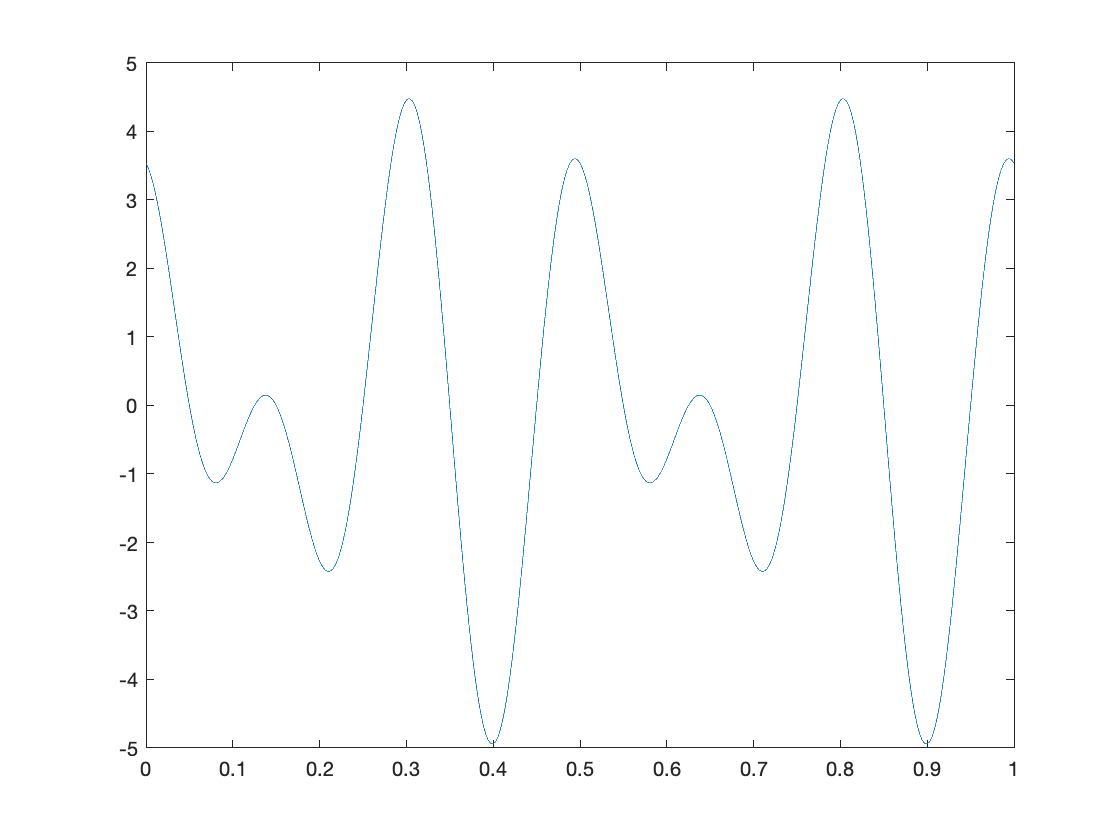

sigVec = AMSin(t,snr,f0,f1,phi0);
plot(t,sigVec)

function sigVec = genSinSig(dataX,snr,freq,phi0)
% Generate a sinusoidal signal
% S = GENSINSIG(X,SNR,F,P)
% Generates a sinusoidal signal = A * sin(2*pi*f0*t+phi0) where A is
% interpreted as signal-to-noise ration(SNR). F is the frequency f0 of the
% signal and P is the initial phase phi0. X is the vector of time stamps where the
% signal is to be computed.

% QYQ 2021-2-21

sigVec = snr * sin(2*pi*freq.*dataX + phi0);

end

function sigVec = LinearChirp(dataX,snr,f0,f1,phi0)
% Generate a linear chirp signal
% S = LINEARCHIRP(T,f0,f1,P0)
% Generates a linear chirp signal. T is the vector of time stamps at which
% the samples of signal are to be computed. snr is the overall amplitude of the signal. f0, f1 is the starting and
% ending frequency of the signal. P is the initial phase phi0.

% QYQ 2021-2-21

sigVec = snr * sin(2*pi.*(f0.*dataX + f1.*dataX.^2)+phi0);

end

function sigVec = SinGausian(dataX,snr,t0,sigma,f0,phi0)
% Generate a sinusoidal signal which is modulated by a Gausian envelope
% S = SINGAUSIAN(T,SNR,t0,S,F,P)
% Generates a Sin-Gausian signal. T is the vector of time stamps, snr is
% the overall amplitude, t0 is the mean time, S is the standard
% deviation, F is the central frequency of the signal, P is the initial
% phase.

% QYQ 2021-2-21

sigVec = snr * exp(-1/2 .* (dataX - t0).^2 / sigma^2) .* sin(2*pi*f0.*dataX+phi0);

end

function sigVec = FMSin(dataX,snr,b,f0,f1)
% Generate frequency modulated sinusoidal signal
% S = FMSIN(T,SNR,b,f0,f1)
% S = A*sin(2*pi*f0*t + b*cos(2*pi*f1*t))

% QYQ 2021-2-21

sigVec = snr * sin(2*pi*f0.*dataX + b*cos(2*pi*f1.*dataX));

end

function sigVec = AMSin(dataX,snr,f0,f1,phi0)
% Generate an amplitude modulated sinusoidal signal
% S = AMSIN(T,SNR,f0,f1,P)
% S = A * cos(2*pi*f1*t) * sin(2*pi*f0+phi0)

% QYQ 2021-2-21

sigVec = snr * cos(2*pi*f1.*dataX) .* sin(2*pi*f0.*dataX + phi0);

end